## Tutorial 4: Two step optimization part one: the cell finding module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a two-photon calcium imaging movie collected following the published guidelines, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information on the imaging and experimental conditions.

### Watching the preprocessed movie

As the first step, we watch the preprocessed movie and ensure that the motion is properly corrected and the spatial filtering does not introduce significant artifacts.

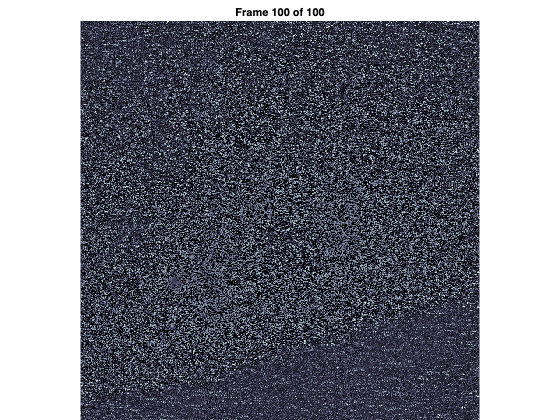

EXTRACT_setup;

if ~exist('jones.h5','file')
    disp(['Downloading 2.93 GB data file jones.h5'])
    websave('jones.h5','https://wds-matlab-community-toolboxes.s3.amazonaws.com/EXTRACT/jones.h5');
end
M = h5read('jones.h5','/data');
config = get_defaults([]);
M_proc = preprocess_movie(M,config);
view_movie(M_proc(:,:,1:100))

From watching the preprocessed movie, it is rather clear that we are aiming to perform cell extraction from a rather low SNR movie, in which the cells are barely visible to the eye. Thus, cell finding module likely needs to be tweaked to account for this fact.

### Cell extraction with defaults

We start with a simple cell extraction using mainly the default parameters.

M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.use_gpu = 0;
output = extractor(M,config);

15-Jul-2024 20:34:30: Signal extraction will run on 1 partitions serially... 
15-Jul-2024 20:34:30: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1528 
	 	 	 	 minimum magnitude: 0.2104 
			 Step #100, found 77 cells... 
	 	 	 77 cells found after a total of 104 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 37 (40 removed) 
	 	 	 End of iter # 2: # cells: 34 (3 removed) 
	 	 	 End of iter # 3: # cells: 34 (0 removed) 
	 	 	 End of iter # 4: # cells: 34 (0 removed) 
	 	 	 End of iter # 5: # cells: 34 (0 removed) 
	 	 	 End of iter # 6: # cells: 34 (0 removed) 
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 34 cells.
15-Jul-2024 20:36:22: Total of 34 cells are found.
15-Jul-2024 20:36:22: Removing duplicate cells...
15-Jul-2024 20:36:22: 34 cells were retained after 

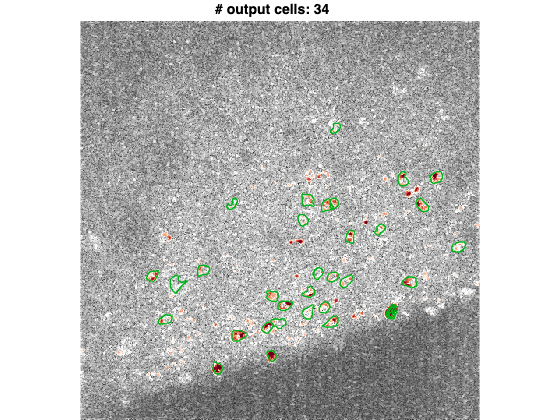

plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])

drawnow

As expected, the cell extraction with default values missed several cells. There may be several reasons, one of which is the failure of the cell finding module. To test this, we can turn off the cell refinement process and watch the cell extraction real-time as it is happening with following the code:

15-Jul-2024 20:36:27: Signal extraction will run on 1 partitions serially... 
15-Jul-2024 20:36:27: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.1528 
	 	 	 	 minimum magnitude: 0.2104 
			 Step #100, found 77 cells... 


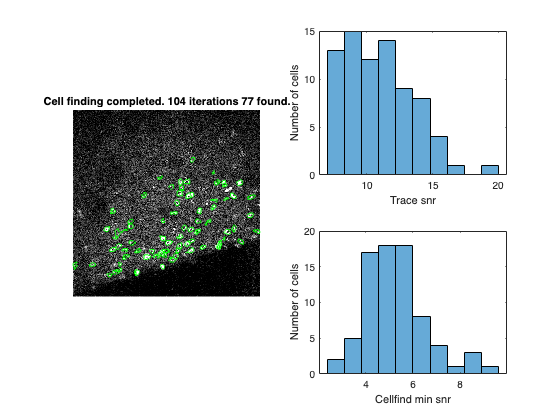

	 	 	 77 cells found after a total of 104 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 77 cells.
15-Jul-2024 20:38:01: Total of 77 cells are found.
15-Jul-2024 20:38:01: Removing duplicate cells...
15-Jul-2024 20:38:01: 77 cells were retained after removing duplicates.
15-Jul-2024 20:38:01: All done with EXTRACT! 


config.max_iter = 0;
config.visualize_cellfinding = 1;
output = extractor(M,config);

Indeed, as can be seen above, cell finding module is missing several low SNR cells that should have been identified.

### Optimizing the cell finding module

To optimize the cell finding module, we will first note that the earlier run had shown an early cutoff for the trace snr values, indicating that more cells might have been found in lower SNR values. Second, the cellfind min snr value was centered around 5 (often should be ~10-100s), a rather low value. Thus, we first pick very low values for both parameters. 

Next, since our main concern is being able to identify cells, we can also decrease the cutoff value for the spatial lowpass filter. This will allow more smoothing of the movie used for the cell finding purposes only.

15-Jul-2024 20:38:02: Signal extraction will run on 1 partitions serially... 
15-Jul-2024 20:38:02: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.0761 
	 	 	 	 minimum magnitude: 0.0287 
			 Step #100, found 98 cells... 
			 Step #200, found 167 cells... 


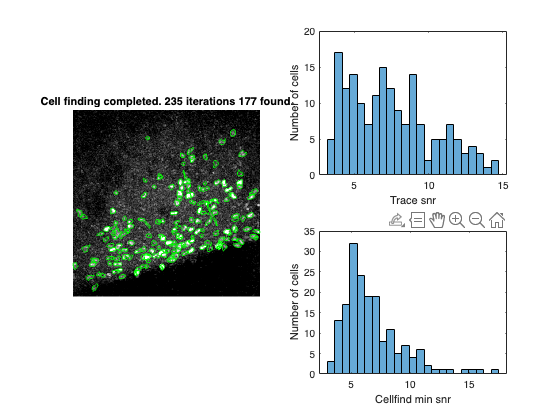

	 	 	 177 cells found after a total of 235 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 177 cells.
15-Jul-2024 20:40:04: Total of 177 cells are found.
15-Jul-2024 20:40:04: Removing duplicate cells...
15-Jul-2024 20:40:04: 177 cells were retained after removing duplicates.
15-Jul-2024 20:40:04: All done with EXTRACT! 


M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 0;
config.visualize_cellfinding = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
output = extractor(M,config);

And voila! We have achieved a satisfactory cell finding process, where almost all cells (but also some garbage) are found. The next tutorial will discuss how to optimize the cell refinement module, which primarily aims to cull away the false-positive candidates.